# Perform elastic characterization of lattice using trial 3 and 4

%% kx = y where k is the elastic const
x = [];
y = [];
counter = 1;

folder3 = "lattice_calibration_data/15x15x15/trial3/";
index3 = ['1';'3';'4';'5';'6'];
folder4 = "lattice_calibration_data/15x15x15/trial4/";
index4 = ['1';'2';'6'];

### Trial 3 data collection

% for i=1:size(index3,1)
%     filename = folder3 + "lattice_data_" + index3(i);
%     load(filename);
%     fz_fil = lowpass(fz,0.1);
%     z_fil = lowpass(z,0.00001,100);
%     t = t_biased;
%     v = diff(z_fil,1,1)*100;
%     v(end+1) = v(end);
%     v_fil = lowpass(v,0.00000001,100);
% 
%     v0 = 2e-4;
%     ts_movs = [];
%     i_movs = [];
%     i = 1;
%     t_counter = 1;
% 
%     length = size(v_fil,1);
% 
%     while true
%         if i>length
%             break;
%         end
%         if abs(v_fil(i)) > v0
%             ts_movs(t_counter) = t(i-5);
%             i_movs(t_counter) = i-5;
%             t_counter = t_counter + 1;
%             i = i+1;
%             while abs(v_fil(i)) > v0
%                 i = i+1;
%             end
%             ts_movs(t_counter) = t(i-1);
%             i_movs(t_counter) = i-1;
%             t_counter = t_counter + 1;
%             i = i+1;
%         else
%             i = i+1;
%         end
%     end
% 
%     ts_movs = ts_movs';
%     i_movs = i_movs';
% 
%     n_movs = size(ts_movs,1);
% 
%     x(counter) = -z_fil(i_movs(2) + 50);
%     y(counter) = (fz_fil(i_movs(3)) + fz_fil(i_movs(11)))/2;
%     counter = counter + 1;
%     x(counter) = -z_fil(i_movs(4) + 50);
%     y(counter) = (fz_fil(i_movs(5)) + fz_fil(i_movs(9)))/2;
%     counter = counter + 1;
% end

### Trial 4 data collection

for i=1:size(index4,1)
    filename = folder4 + "lattice_data_" + index4(i);
    load(filename);
    fz_fil = lowpass(fz,0.1);
    z_fil = lowpass(z,0.00001,100);
    t = t_biased;
    v = diff(z_fil,1,1)*100;
    v(end+1) = v(end);
    v_fil = lowpass(v,0.00000001,100);

    v0 = 2e-4;
    ts_movs = [];
    i_movs = [];
    i = 1;
    t_counter = 1;

    length = size(v_fil,1);

    while true
        if i>length
            break;
        end
        if abs(v_fil(i)) > v0
            ts_movs(t_counter) = t(i-5);
            i_movs(t_counter) = i-5;
            t_counter = t_counter + 1;
            i = i+1;
            while abs(v_fil(i)) > v0
                i = i+1;
            end
            ts_movs(t_counter) = t(i-1);
            i_movs(t_counter) = i-1;
            t_counter = t_counter + 1;
            i = i+1;
        else
            i = i+1;
        end
    end

    ts_movs = ts_movs';
    i_movs = i_movs';

    n_movs = size(ts_movs,1);

    x(counter) = -z_fil(i_movs(2) + 50);
    y(counter) = (fz_fil(i_movs(3)) + fz_fil(i_movs(11)))/2;
    counter = counter + 1;
    x(counter) = -z_fil(i_movs(4) + 50);
    y(counter) = (fz_fil(i_movs(5)) + fz_fil(i_movs(9)))/2;
    counter = counter + 1;
end

scatter(x,y,20,"red","filled");
hold on;
xlim([-5e-3,0]);
ylim([-10,0]);
grid on;

% Calculate the elastic constant k based on the relationship kx = y
k = y ./ x;
meanK = mean(k(~isnan(k))); % Calculate the mean of k, ignoring NaN values
disp(['Mean Elastic Constant: ', num2str(meanK)]);

Mean Elastic Constant: 1756.6347


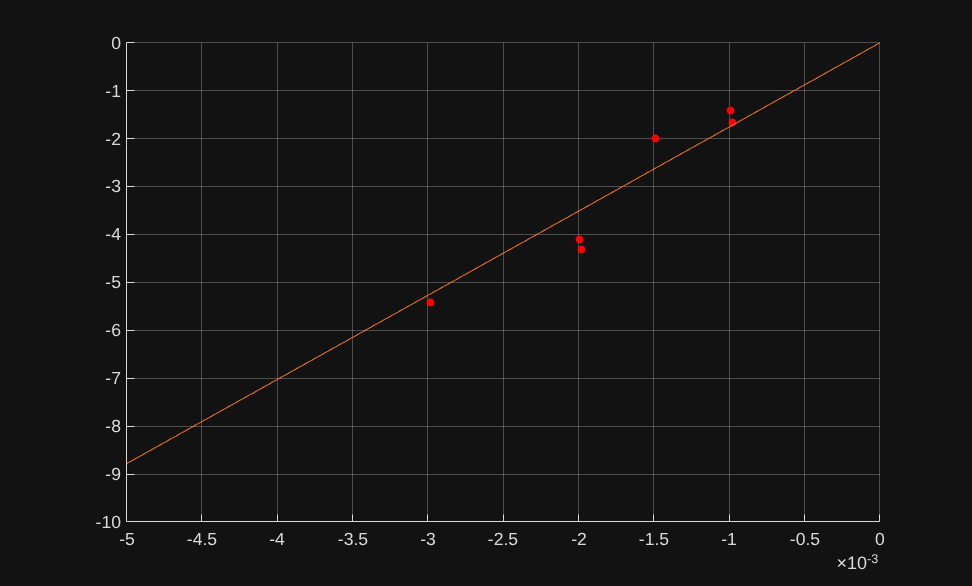

k = meanK;
plot((-5e-3:1e-5:0.0),k*(-5e-3:1e-5:0.0));
hold off

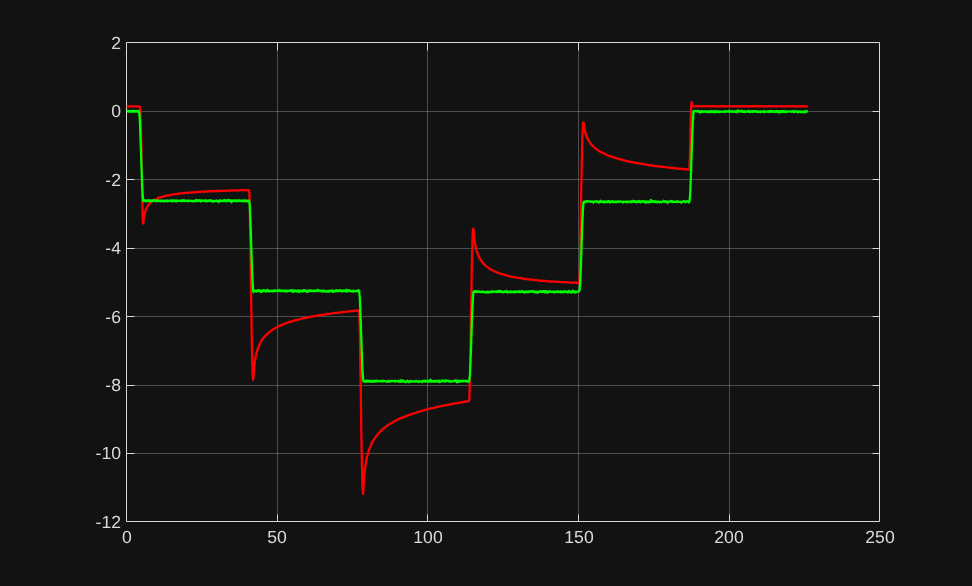

figure;
load(folder4 + "lattice_data_" + index4(3));
plot(t_biased,fz,"LineWidth",1.3,"Color","red");
hold on;
plot(t_biased,-k*z,"LineWidth",1.3,"Color","green");
grid on;
hold off;